# Voltage limit

fprintf('1/sqrt(2), %.8f \n', 1/sqrt(2) )

1/sqrt(2), 0.70710678 


fprintf('1/sqrt(3), %.8f \n', 1/sqrt(3))

1/sqrt(3), 0.57735027 


fprintf('2/3, %.8f\n', 2/3)

2/3, 0.66666667





Vdc_norm=700; % Nominal
Vdc_min=600;
margin_V=0.9;
Vll_min=600*margin_V;

Vpk_criteria=Vdc_norm;
Vrms_criteria=Vdc_norm/sqrt(2);
Vdq_criteria=Vll_min;




total_effy=readtable('Z:\01_Codes_Projects\Testdata_post\Total_Effy_skew_rework_HDEV.csv');


Input.p=6

Input = 다음 필드를 포함한 struct :
    p: 6


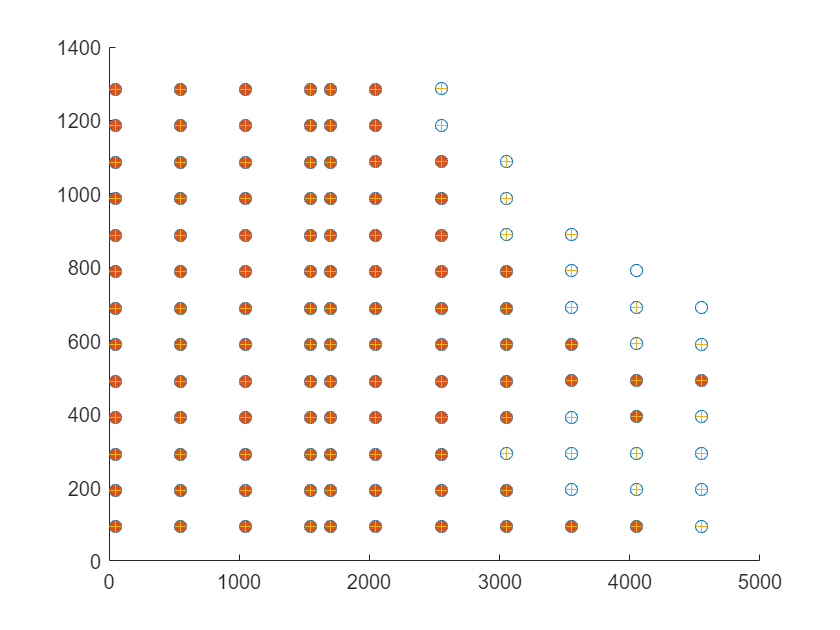

p=Input.p;
%% load total_effy
Ipk=total_effy.Current_pk;
beta=total_effy.Current_phase;
Rs=total_effy.Rs;
lam_d=total_effy.Lamda_d;
lam_q=total_effy.Lamda_q;
RPM=total_effy.RPM;

%% Plot with calced value
scatter(total_effy.RPM,total_effy.Torque)
hold on;
Vpk_idx=Vpk_criteria>total_effy.Vll_pk;
scatter(total_effy.RPM(Vpk_idx),total_effy.Torque(Vpk_idx),'filled','DisplayName','Vllpk')
hold on;

Vrms_idx=Vrms_criteria>total_effy.Vll_rms;
scatter(total_effy.RPM(Vrms_idx),total_effy.Torque(Vrms_idx),'+','DisplayName','Vllrms')

## Vdq calc

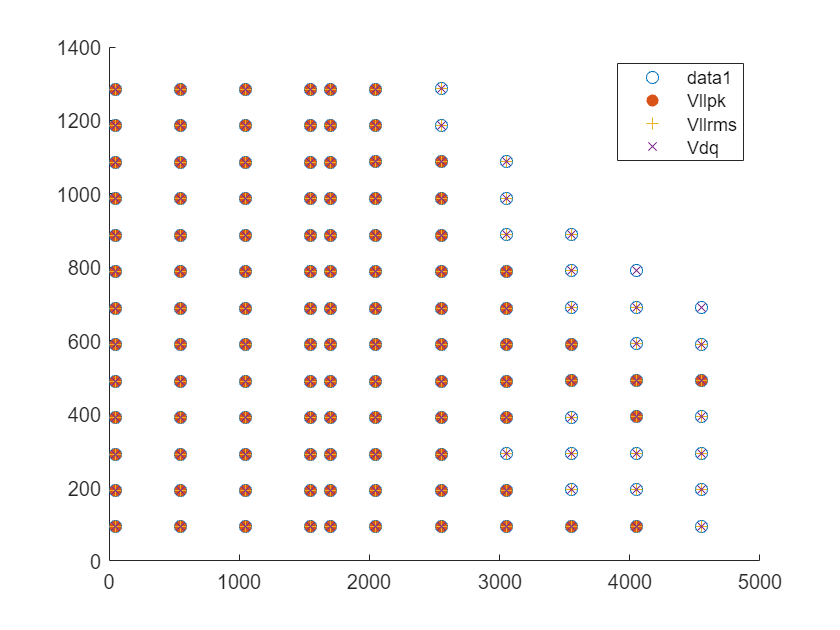

id=Ipk.*cos(deg2rad(beta));
iq=Ipk.*sin(deg2rad(beta));

V_d=Rs.*id-2*pi().*RPM/60*p/2.*lam_q;
V_q=Rs.*iq+2*pi().*RPM/60*p/2.*lam_d;
V_dq=sqrt(V_d.^2+V_q.^2);

Vdq_i=Vdq_criteria>V_dq;
scatter(total_effy.RPM(Vdq_i),total_effy.Torque(Vdq_i),'x','DisplayName','Vdq');
legend



sqrt(Vd_Peak.^2+Vq_Peak.^2)./Voltage_Line_RMS

'Vd_Peak'은(는) 인식할 수 없는 함수 또는 변수입니다.